Data zajęć: 11.10.2023

Data wykonania sprawozdania: 18.10.2023

Imię i nazwisko: Szymon Turkiewicz

Sprawozdanie z zajęć nr 2

a) Utwórz dwie zmienne (a i b), przypisz im wartości (23, 5). Następnie podziel większą liczbę przez mniejszą, a wynik zaokrąglij. Rezultat zapamiętaj w zmiennej c. Z kolei w zmiennej d zapamiętaj resztę z dzielenia. Wskazówka – aby znaleźć potrzebne funkcje skorzystaj z systemu pomocy MATLABa.

a=23;
b=5;
c = round(a/b);
d=rem(a,b); %opcjonalnie mod

Jest kilka sposobów na które można zaokrąglić liczbe w matlbaie(ceil,round,floor), jak też na obliczanie reszty z dzielenia (rem,mod)

b) Utwórz wektor kolumnowy v zawierający liczby: 0 5 0 4 0. 

v = [0; 5; 0; 4; 0];

c) Utwórz tablicę R2 o rozmiarze [5x3] zawierającą liczby pseudolosowe o rozkładzie normalnym i zadanych parametrach: średnia = 3, odchylenie standardowe = 5. 

R2=normrnd(5,3,5,3);

d) Połącz wektor v z tablicą R2, tak aby wynikowa tablica miała rozmiar 5 wierszy i 4 kolumny. 

newR2= [R2, v];

e) Utwórz wektor x w przedziale 0 – 2π, z krokiem π/10. Utwórz wektor y będący rezultatem funkcji sinus na elementach wektora x. Zwizualizuj funkcję y=f(x) przy pomocy wykresu typu PLOT.

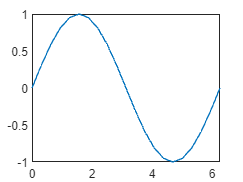

x=0:pi/10:2*pi;
y=sin(x);
plot(x,y)

 f) Wyznacz średnią z wektora y. Jaki wymiar będzie miał rezultat? 

avg=mean(y);
size(avg)

ans =      1     1


rezultat ma wymiar 1x1 czyli jest skalarem co oznacza że y jest wektorem

g) Spróbuj rozwiązać układ równań

A=[1 2 3; -1 1 4;-1 -2 -3];
B=[5;1;-5];
sizeB =size(B);
rankA =rank(A);

Jak wynika z Twierdzenia Kroneckera-Capellego układ Ax=B

jest rozwiązywalny(ma tylko jedno rozwiązanie) gdy rząd macierzy A jest większy, albo równy  ilości niewiadomych, czego użyłem do napisania instrukcji warunkowych które to sprawdzą

if rankA<sizeB(1)
    fprintf("Układ nie jest rozwiazywalny")
else
    fprintf("Układ jest rozwiązywalny")
end

Układ nie jest rozwiazywalny

h) Wczytaj do MATLABa dane z pliku exampledata.mat (kliknij 2x na plik w przeglądarce plików środowiska MATLAB „Current folder”), a następnie sprawdź jakie zmienne zostały zaimportowane do MATLABa 

- Tablica RGB ma trzy wymiary (M-wierszy, N-kolumn i K-warstw) i reprezentuje obraz w formacie RGB o rozmiarze [M,N]. Każda warstwa zawiera wartość osobnej składowej koloru pikseli obrazu. - Dokonaj konwersji każdego piksela obrazu korzystając ze wzoru

                                                 [  0.299      0.587       0.114]

     [ 𝑌 𝐶𝑏 𝐶𝑟] = [ 0 128 128 ] +  [−0.169    −0.331          0.5][ 𝑅 𝐺 𝐵 ]

                                                  [     0.5    −0.419     −0.081]

load exampledata.mat

Załadowanie danych

R=RGB(:,:,1);
G=RGB(:,:,2);
B=RGB(:,:,3);
R1=R(:)';
G1=G(:)';
B1=B(:)';
A=[R1;G1;B1];

Utworzenie macierzy A, który zawiera warstwy rgb jako wektory kolumnowe

B=[0;128;128]+[0.299 0.587 0.114;-0.169 -0.331 0.5;0.5 -0.419 -0.081]*A;

Y=B(1,:);
Cb=B(2,:);
Cr=B(3,:);

Przemnożenie tak uzyskanej macierzy A przez macierz B która została podana w treści zadania a potem rozdzielenie jej na poszczególne wektory


Y=reshape(Y,650,600);
Cb=reshape(Cb,650,600);
Cr=reshape(Cr,650,600);

Utworzenie macierzy z tych wektorów

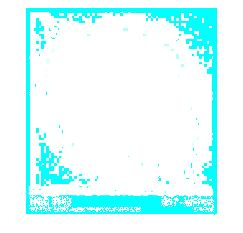

YCbCr(:,:,1)= Y;
YCbCr (:,:,2)=Cb;
YCbCr (:,:,3)=Cr;
imshow(YCbCr)

Połączenie tych macierzy w jeden trójwarstwowy element i wyświetlenie jego reprezentacji graficznej za pomocą odpowiedniej komendy

i) Utwórz następujące zmienne: a=pi; b=ones(1,1, 'uint8'); a następnie dodaj je do siebie tak aby uzyskać rezultat w typie danych double

a=pi;
b=ones(1,1, 'uint8');
b=double(b);
a+b

ans = 4.1416

typ zmiennych w elemencie b jest zadefiniowany w funkcji ones() i by potem by być w stanie dodawać do siebie dwa elementy powinny one być tego samego typu i by to zrobić należy użyć funkcji double by zmienić typ danej zmiennej na double

j) Wygeneruj losowy ciąg znaków (tablica znakowa o rozmiarze [10x1]) składający się z następujących liter: a,b,c,d,e,f,g.

litery='abcdefg'

litery = 'abcdefg'

X=litery(randi(length(litery),1,10))

X = 'bbedcfedgc'

Na początku należy utworzyć zbiór wszystkich dostępnych liter, a potem za pomocą funkcji randi utworzyć dziesięcio elementowy wektor o pseudolosowych liczbach całkowitych i potem po "włożeniu" go do "funkcji" litery otrzymuje się ciąg z literami odpowiadającymi swoim indeksem w litery wylosowanym pseudolosowym liczbom w wylosowanym wektorze 

Wnioski:

Matlab jest oprogramowaniem przystosowanym do obliczeń na wektorach i macierzach, a dużo danych np. tych służących do wyświetlania pikseli przez monitor, można wstawić do takiej macierzy i dokonywać na niej odpowiednich operacji przez co można wpływać na wszystkie piksele naraz

Można też zauważyć, że matlab domyślnie stwierdza typ danych zmiennej i należy wymuszać dany typ za pomocą odpowiednich funkcji

Oprogramowanie to ma także inne zalety i jedną z nich jest możliwość dokładnego wyświetlania pomiarów czy danych na wykresie i dużą kontrolę nad wyglądem danego wykresu (drobną wadą jest to, że jest to możliwe za pomocą komend a nie interfejsu graficznego tak jak np. w excelu co powoduje, że matlab jest mniej przyjazny dla początkujących) 

Przy wykonywaniu tego ćwiczenia nauczyłem się wielu przydatnych funkcji służących do łączenia macierzy i wektorów w odpowiedni sposób i podstawowych operacji na nich, pojawiły się w tym ćwiczeniu również instrukcje warunkowe(przynajmniej w mojej implementacji) i funkcje służące do generowania liczb pseudolosowych